n = 5;
lgndr = 1;
for i = 1:n
    t = [1, 0, -1];
    lgndr = conv(lgndr, t);
end
for i = 1:n
    lgndr = diff_(lgndr);
end
lgndr

lgndr =        30240           0      -33600           0        7200           0


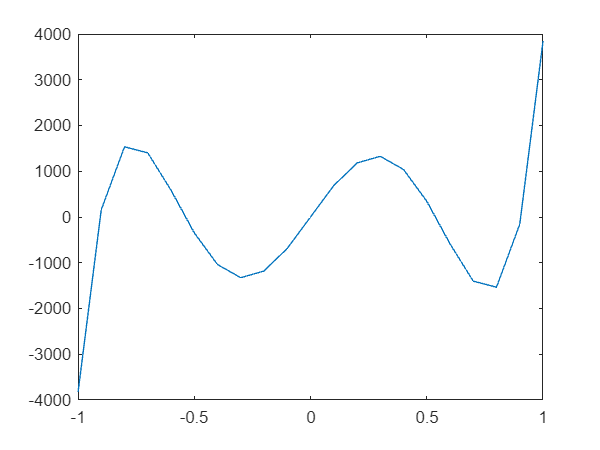


xx = -1:0.1:1;
plot(xx, polyval(lgndr, xx))


lgndr_r = roots(lgndr)

lgndr_r =          0
   -0.9062
   -0.5385
    0.9062
    0.5385


for k=1:length(lgndr_r)
    A=1;
    for j=[1:k-1, k+1:length(lgndr_r)]
        A=conv(A, [1/(lgndr_r(k)-lgndr_r(j)), -lgndr_r(j)/(lgndr_r(k)-lgndr_r(j))]);
    end
    b_k(k) = integ_(A);
end

left = 1;
right = 2;

x = (right - left)/2 * lgndr_r + (right + left)/2;
y = sin(x);

b_k_x_k = 0;
for i = 1:length(x)
    b_k_x_k = b_k_x_k + b_k(i)*y(i);
end
integ_res = (right - left)/2 * b_k_x_k

integ_res = 0.9564

integ_real = -cos(2) + cos(1)

integ_real = 0.9564